# **First Optimal Control Project**

# **Non-interpolated Dynamic Programming**

## Ali Eidizadeh                            ali80ei@gmail.com

## Amirhadi Keyvan     amirhadikeyvan@gmail.com

%% Problem Setup
    clc;
    clear;
    
    fprintf('=== Optimal Control using Dynamic Programming ===\n');

=== Optimal Control using Dynamic Programming ===


    
    % Discretization parameters
    q_x = input('Enter state quantization step (e.g., 0.1): ');
    q_u = input('Enter input quantization step (e.g., 0.1): ');
    
    % Create quantized spaces
    states = 0:q_x:1.5;
    inputs = -1:q_u:1;
    N = 10;  % Number of stages
    
    fprintf('\nState grid (%d points):\n', length(states));


State grid (4 points):


    disp(states);

         0    0.5000    1.0000    1.5000



    fprintf('Control grid (%d points):\n', length(inputs));

Control grid (5 points):


    disp(inputs);

   -1.0000   -0.5000         0    0.5000    1.0000



    
    %% Backward Pass - Direct Grid Lookup
    % Initialize cost-to-go and optimal control tables
    J = cell(1, N+1);
    U_opt = cell(1, N);
    J{N+1} = states.^2;  % Terminal cost
    
    fprintf('\n=== Backward Pass Calculations ===\n');


=== Backward Pass Calculations ===


    for k = N:-1:1
        J_current = inf(1, length(states));
        U_current = nan(1, length(states));
        
        for i = 1:length(states)
            min_cost = inf;
            best_u = 0;
            x = states(i);
            
            for j = 1:length(inputs)
                u = inputs(j);
                x_next = x + u;
                
                % State constraints check
                if x_next < 0 || x_next > 1.5
                    continue;
                end
                
                % Find exact state index (no interpolation)
                next_idx = find(abs(states - x_next) < 1e-9);
                
                if k == N
                    cost_next = x_next^2;
                else
                    cost_next = J{k+1}(next_idx);
                end
                
                total_cost = 2*u^2 + cost_next;
                
                if total_cost < min_cost
                    min_cost = total_cost;
                    best_u = u;
                end
            end
            
            J_current(i) = min_cost;
            U_current(i) = best_u;
        end
        
        J{k} = J_current;
        U_opt{k} = U_current;
        
        % Display stage table
        fprintf('\nStage k = %d\n', k-1);
        fprintf('%-10s %-12s %-12s\n', 'State', 'Optimal Cost', 'Optimal Control');
        for i = 1:length(states)
            fprintf('%-10.2f %-12.4f %-12.4f\n', states(i), J{k}(i), U_opt{k}(i));
        end
    end


Stage k = 9


State      Optimal Cost Optimal Control


0.00       0.0000       0.0000      
0.50       0.2500       0.0000      
1.00       0.7500       -0.5000     
1.50       1.5000       -0.5000     



Stage k = 8


State      Optimal Cost Optimal Control


0.00       0.0000       0.0000      
0.50       0.2500       0.0000      
1.00       0.7500       -0.5000     
1.50       1.2500       -0.5000     



Stage k = 7


State      Optimal Cost Optimal Control


0.00       0.0000       0.0000      
0.50       0.2500       0.0000      
1.00       0.7500       -0.5000     
1.50       1.2500       -0.5000     



Stage k = 6


State      Optimal Cost Optimal Control


0.00       0.0000       0.0000      
0.50       0.2500       0.0000      
1.00       0.7500       -0.5000     
1.50       1.2500       -0.5000     



Stage k = 5


State      Optimal Cost Optimal Control


0.00       0.0000       0.0000      
0.50       0.2500       0.0000      
1.00       0.7500       -0.5000     
1.50       1.2500       -0.5000     



Stage k = 4


State      Optimal Cost Optimal Control


0.00       0.0000       0.0000      
0.50       0.2500       0.0000      
1.00       0.7500       -0.5000     
1.50       1.2500       -0.5000     



Stage k = 3


State      Optimal Cost Optimal Control


0.00       0.0000       0.0000      
0.50       0.2500       0.0000      
1.00       0.7500       -0.5000     
1.50       1.2500       -0.5000     



Stage k = 2


State      Optimal Cost Optimal Control


0.00       0.0000       0.0000      
0.50       0.2500       0.0000      
1.00       0.7500       -0.5000     
1.50       1.2500       -0.5000     



Stage k = 1


State      Optimal Cost Optimal Control


0.00       0.0000       0.0000      
0.50       0.2500       0.0000      
1.00       0.7500       -0.5000     
1.50       1.2500       -0.5000     



Stage k = 0


State      Optimal Cost Optimal Control


0.00       0.0000       0.0000      
0.50       0.2500       0.0000      
1.00       0.7500       -0.5000     
1.50       1.2500       -0.5000     



=== Optimal Results ===


Initial state: 1.50


Total cost: 1.2500



Optimal Control Sequence:


  Columns 1 through 9

   -0.5000   -0.5000         0         0         0         0         0         0         0

  Column 10

         0




State Trajectory:


  Columns 1 through 9

    1.5000    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000

  Columns 10 through 11

    0.5000    0.5000



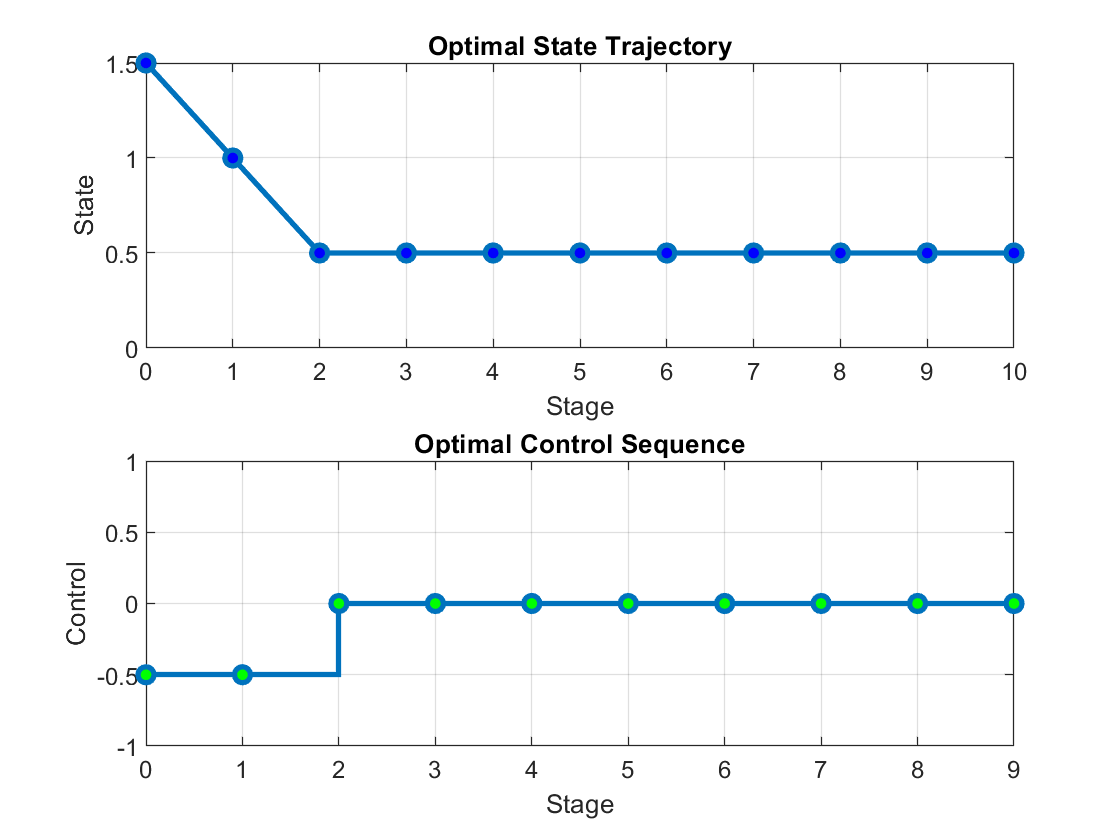

    
    %% Forward Pass Simulation - Direct Grid Access
    while true
        x0 = input('\nEnter initial state (0-1.5) or "q" to quit: ', 's');
        if strcmpi(x0, 'q'), break; end
        x0 = str2double(x0);
        
        if isnan(x0) || x0 < 0 || x0 > 1.5
            fprintf('Invalid initial state!\n');
            continue;
        end
        
        % Snap initial state to grid
        [~, start_idx] = min(abs(states - x0));
        x0 = states(start_idx);
        
        % Simulate trajectory
        x_traj = zeros(1, N+1);
        u_seq = zeros(1, N);
        x_traj(1) = x0;
        
        for k = 1:N
            % Get exact state index
            current_idx = find(abs(states - x_traj(k)) < 1e-9);
            u = U_opt{k}(current_idx);
            
            % State update
            x_next = x_traj(k) + u;
            
            % Snap next state to grid
            [~, next_idx] = min(abs(states - x_next));
            x_traj(k+1) = states(next_idx);
            u_seq(k) = u;
        end
        
        % Calculate total cost
        total_cost = x_traj(end)^2 + 2*sum(u_seq.^2);
        
        %% Display Results
        fprintf('\n=== Optimal Results ===\n');
        fprintf('Initial state: %.2f\n', x0);
        fprintf('Total cost: %.4f\n', total_cost);
        
        fprintf('\nOptimal Control Sequence:\n');
        disp(u_seq);
        
        fprintf('\nState Trajectory:\n');
        disp(x_traj);
        
        %% Plotting
        close all;
        figure;
        
        subplot(2,1,1);
        plot(0:N, x_traj, 'o-', 'LineWidth', 2, 'MarkerFaceColor', 'b');
        title('Optimal State Trajectory');
        xlabel('Stage');
        ylabel('State');
        grid on;
        ylim([0 1.5]);
        
        subplot(2,1,2);
        stairs(0:N-1, u_seq,'o-', 'LineWidth', 2, 'MarkerFaceColor', 'g');
        title('Optimal Control Sequence');
        xlabel('Stage');
        ylabel('Control');
        grid on;
        ylim([-1 1]);
    end

    
    fprintf('\nProgram terminated.\n');


Program terminated.
